# Algoritmos Numéricos por Computadora

# Tercer parcial - Otoño 2019

Cambia el nombre del script a NombreClaveúnica (ej: Marcelo123456).

Sube tu archivo resultado a comunidad $\to$ tercerParcial antes de las 10am.

Al correr tu script deben desplegarse los resultados.

## 1. Ecuación diferencial ordinaria de primer orden

Resuelve el siguiente problema de valor inicial en el intervalo de t=0 a t=2, donde y(0)=1. Grafica la solución $y\left(t\right)$.


$$\frac{\textrm{d}}{\textrm{d}t}y=yt^2 -1\ldotp 1y$$


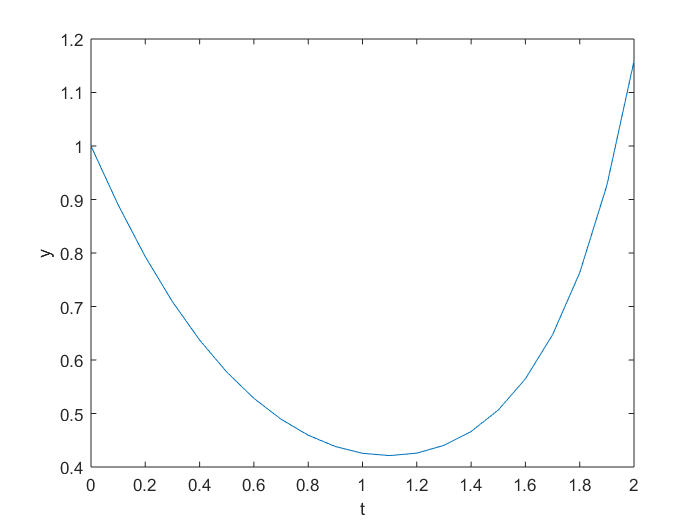

%
y0=1;
f= @(t,y) y*t^2-1.1*y;
h=0.1;
t0=0;
tf=2;
[t,y] = ivps(f,t0,y0,h,tf,'euler');
plot(t,y)
xlabel('t');
ylabel('y');

## 2. Sistema de dos ecuaciones diferenciales ordinarias de primer orden

Resuelve el siguiente sistema en el rango de x=0 a 0.4, con y(0)=2 y z(0)=4. Grafica la solución $y\left(t\right)\;$y $z\left(t\right)$.


$$\frac{\textrm{d}}{\textrm{d}t}y=-2y+5e^{-t}$$



$$\frac{\textrm{d}}{\textrm{d}t}z=-\frac{yz^2 }{2}$$


% 
f= @(t,yz) [-2*y(1)+ 5*exp(-t); (-y(1)*y(2)^2)/2];
y0=[2;4]

y0 =      2
     4


t0=0;
tf=0.4;
[t,y] = ivps(f,t0,y0,0.1,tf,'rk4')

t =                    0   0.100000000000000   0.200000000000000   0.300000000000000   0.400000000000000


y =    2.000000000000000   2.275812926336568   2.506346266071082   2.695908941574859   2.848399827040876
   4.000000000000000   3.960395000000000   3.920790000000000   3.881185000000000   3.841580000000000


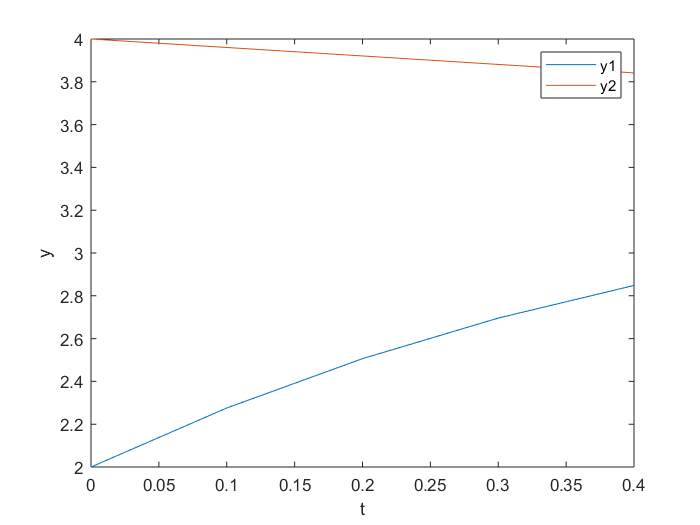

plot(t,y)
xlabel('t');
ylabel('y');
legend('y1','y2');

## 3. Ecuación diferencial ordinaria de segundo orden

Resuelve el siguiente problema de t=0 a 5.


$$\frac{{\textrm{d}}^2 }{\textrm{d}t^2 }y+0\ldotp 6\;\frac{\textrm{d}}{\textrm{d}t}y+8y=0$$


donde y(0)=4 y y'(0)=0. Grafica la solución $y\left(t\right)$.

% 
f = @(t,yz) [yz(2)+ 0.6*yz(1);8*y(1)];
y0=[4;0]

y0 =      4
     0


t0=0;
tf=5;
[t,y] = ivps(f,t0,y0,0.1,tf,'euler')

t =                    0   0.100000000000000   0.200000000000000   0.300000000000000   0.400000000000000   0.500000000000000   0.600000000000000   0.700000000000000   0.800000000000000   0.900000000000000   1.000000000000000   1.100000000000000   1.200000000000000   1.300000000000000   1.400000000000000   1.500000000000000   1.600000000000000   1.700000000000000   1.800000000000000   1.900000000000000   2.000000000000000   2.100000000000000   2.200000000000000   2.300000000000000   2.400000000000000   2.500000000000000   2.600000000000000   2.700000000000000   2.800000000000000   2.900000000000000   3.000000000000000   3.100000000000000   3.200000000000000   3.300000000000000   3.400000000000000   3.500000000000000   3.600000000000000   3.700000000000000   3.800000000000000   3.900000000000000   4.000000000000000   4.100000000000000   4.200000000000000   4.300000000000000   4.400000000000000   4.500000000000000   4.600000000000000   4.700000000000000   4.800000000000000   4.90000000000

y = 	1.0e+02 *

   0.040000000000000   0.042400000000000   0.046544000000000   0.052536640000000   0.060488838400000   0.070518168704000   0.082749258826240   0.097314214355814   0.114353067217163   0.134014251250193   0.156455106325205   0.181842412704717   0.210352957467000   0.242174134915020   0.277504583009921   0.316554857990516   0.359548149469947   0.406721038438144   0.458324300744433   0.514623758789099   0.575901184316445   0.642455255375432   0.714602570697957   0.792678724939835   0.877039448436225   0.968061815342398   1.066145524262942   1.171714255718719   1.285217111061842   1.407130137725553   1.537957945989086   1.678235422748431   1.828529548113337   1.989441321000137   2.161607800260145   2.345704268275754   2.542446524372299   2.752593315834637   2.976948914784716   3.216365849671798   3.471747800652106   3.744052668691233   4.034295828812706   4.343553578541469   4.672966793253956   5.023744800849194   5.397169488900144   5.794599658234153   6.217475637728203   6

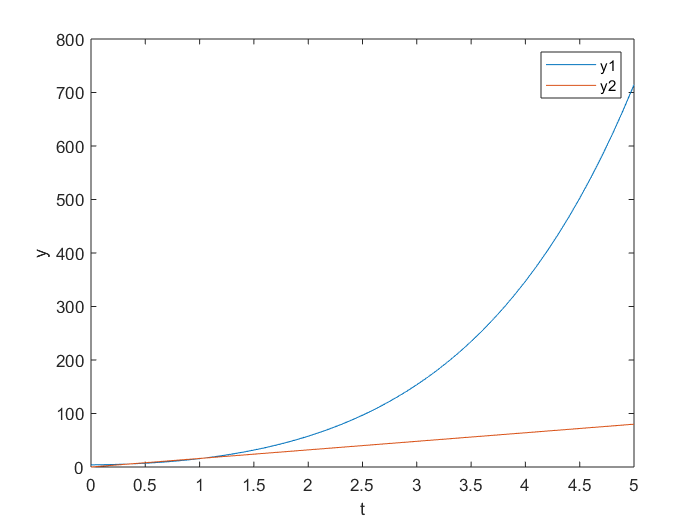

plot(t,y)
xlabel('t');
ylabel('y');
legend('y1','y2');

## 4. Sistema masa - resortes con fricción

En el sistema de dos masas y tres resortes, existe ahora adicionalmente una fuerza de fricción sobre cada masa $F_i =-b\frac{\mathrm{d}}{\mathrm{d}t}x_i \;$. Considera que $b=0\ldotp 0125$ y resuelve el sistema amortiguado.

Calcula los valores propios de la matriz $M_d$. Determina el recíproco de la parte real de cada uno.  Encuentra el mayor valor (*dominant time constant*). Multiplica este valor por 4 y verifica que obtienes el tiempo que toma la respuesta en volverse aproximadamente cero.

%
h = 0.01;
m=0.05*ones(2,1); %masas 
k=0.01*ones(3,1); %resortes
b = 0.0125; %fricción

xci=0.025;
xv0 = [xci*0.5;-xci; 0; 0]

xv0 =    0.012500000000000
  -0.025000000000000
                   0
                   0


Md=[0, 0, 1, 0; 0, 0, 0, 1;-(k(1)+k(2))/m(1),k(2)/m(1), -b/m(1),0; k(2)/m(2),-(k(2)+k(3))/m(2),0, -b/m(2)];

Md =                    0                   0   1.000000000000000                   0
                   0                   0                   0   1.000000000000000
  -0.400000000000000   0.200000000000000  -0.250000000000000                   0
   0.200000000000000  -0.400000000000000                   0  -0.250000000000000



f=@ (t,xv) Md*xv;
t0=0;
h=0.001;
tf=20;
[t,xv]=ivps(f,t0,xv0,h,tf,'rk4')

t =                    0   0.001000000000000   0.002000000000000   0.003000000000000   0.004000000000000   0.005000000000000   0.006000000000000   0.007000000000000   0.008000000000000   0.009000000000000   0.010000000000000   0.011000000000000   0.012000000000000   0.013000000000000   0.014000000000000   0.015000000000000   0.016000000000000   0.017000000000000   0.018000000000000   0.019000000000000   0.020000000000000   0.021000000000000   0.022000000000000   0.023000000000000   0.024000000000000   0.025000000000000   0.026000000000000   0.027000000000000   0.028000000000000   0.029000000000000   0.030000000000000   0.031000000000000   0.032000000000000   0.033000000000000   0.034000000000000   0.035000000000000   0.036000000000000   0.037000000000000   0.038000000000000   0.039000000000000   0.040000000000000   0.041000000000000   0.042000000000000   0.043000000000000   0.044000000000000   0.045000000000000   0.046000000000000   0.047000000000000   0.048000000000000   0.04900000000

xv =    0.012500000000000   0.012499995000417   0.012499980003337   0.012499955011270   0.012499920026729   0.012499875052236   0.012499820090317   0.012499755143504   0.012499680214335   0.012499595305355   0.012499500419112   0.012499395558163   0.012499280725070   0.012499155922399   0.012499021152723   0.012498876418623   0.012498721722682   0.012498557067492   0.012498382455648   0.012498197889754   0.012498003372417   0.012497798906252   0.012497584493877   0.012497360137920   0.012497125841010   0.012496881605786   0.012496627434890   0.012496363330971   0.012496089296684   0.012495805334689   0.012495511447652   0.012495207638245   0.012494893909147   0.012494570263040   0.012494236702613   0.012493893230563   0.012493539849589   0.012493176562398   0.012492803371703   0.012492420280221   0.012492027290677   0.012491624405801   0.012491211628326   0.012490788960996   0.012490356406556   0.012489913967759   0.012489461647364   0.012488999448134   0.012488527372839   0.0124880454

x=xv(1:2,:);
v=xv(3:4,:)

v =                    0  -0.009998749020962  -0.019994992168730  -0.029988723572947  -0.039979937366357  -0.049968627684806  -0.059954788667245  -0.069938414455732  -0.079919499195436  -0.089898037034640  -0.099874022124742  -0.109847448620262  -0.119818310678837  -0.129786602461233  -0.139752318131342  -0.149715451856185  -0.159675997805917  -0.169633950153828  -0.179589303076349  -0.189542050753049  -0.199492187366643  -0.209439707102992  -0.219384604151109  -0.229326872703155  -0.239266506954450  -0.249203501103470  -0.259137849351853  -0.269069545904399  -0.278998584969076  -0.288924960757018  -0.298848667482534  -0.308769699363106  -0.318688050619393  -0.328603715475233  -0.338516688157649  -0.348426962896848  -0.358334533926224  -0.368239395482365  -0.378141541805050  -0.388040967137255  -0.397937665725154  -0.407831631818126  -0.417722859668750  -0.427611343532816  -0.437497077669322  -0.447380056340479  -0.457260273811713  -0.467137724351668  -0.477012402232210  -0.48688430172

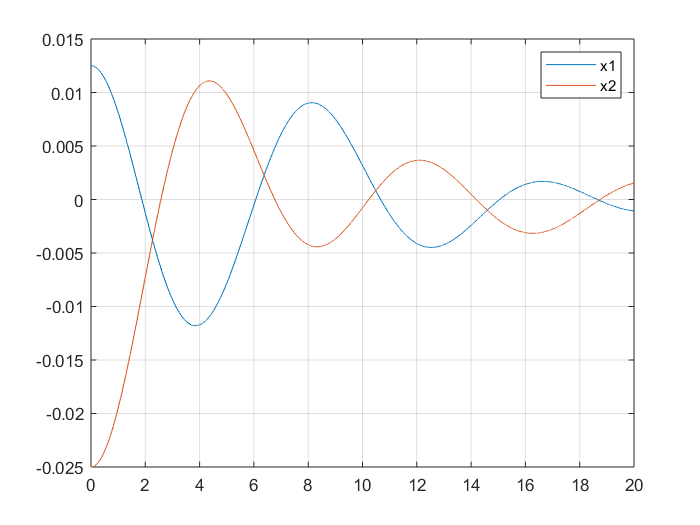

plot(t,x);
grid on;
legend('x1','x2');

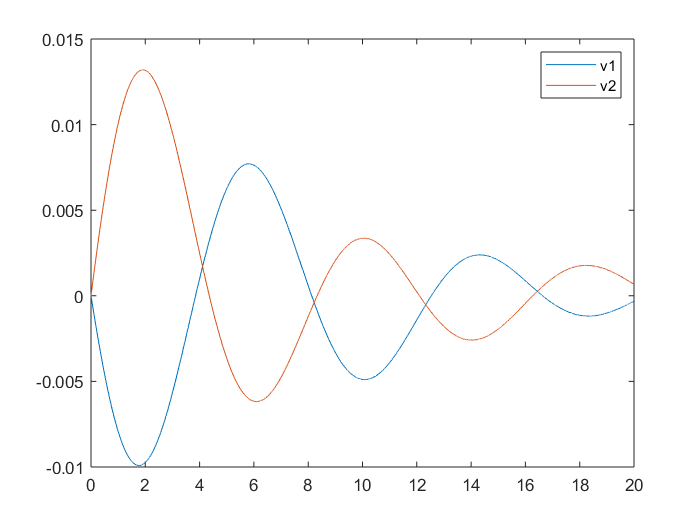

plot(t,v);
legend('v1','v2');

lambda=eig(M)

lambda =  -0.125000000000000 + 0.764444242571033i
 -0.125000000000000 - 0.764444242571033i
 -0.125000000000000 + 0.429389100932942i
 -0.125000000000000 - 0.429389100932942i


a=sqrt(lambda)

a =   0.569910812865260 + 0.670670063906793i
  0.569910812865260 - 0.670670063906793i
  0.401381112846605 + 0.534889519199974i
  0.401381112846605 - 0.534889519199974i


w=imag(a)

w =    0.670670063906793
  -0.670670063906793
   0.534889519199974
  -0.534889519199974


periodo=(2*pi)./w

periodo =    9.368519105473000
  -9.368519105473000
  11.746697367668101
 -11.746697367668101


## 5. Problema con valores en la frontera

Grafica la solución $y\left(t\right)\;$de $7\frac{{\textrm{d}}^2 }{\textrm{d}t^2 }y-2\frac{\textrm{d}}{\textrm{d}t}y-y+t=0$ con las condiciones de frontera $y\left(0\right)=5$ y$y\left(20\right)=8$.

(Hint: Verifica que$\;y^' \left(0\right)$ está entre -1 y -0.5).

% 
f = @(t,yz) [7*yz(2)-2*yz(1);-yz(1)+t];
a=0;
b=20;
ya=5;
yb=8;
h=0.01;
d = shooting(f,a,b,ya,yb,h,-1)

d =   11.714285727690470


d = shooting(f,a,b,ya,yb,h,-0.5)

d =   11.714285724872656


g = @(s) shootingF(f,a,b,ya,yb,h,s)
g(-1)
g(-0.5)
[s, i] = biseccion(g,-1,-0.5)
y0= [ya;s]
[t,y] = ivps(f1,a,y0,h,b,'euler');
plot(t,y(1,:));

function [t,y] = ivps(f,t0,y0,h,tf,metodo)
 %solucionador de problemas con valor inicial
 % y' = f(t,y)   y(0)=y0
 
    switch metodo
        case 'euler'
            solver = @euler; 
            
        case 'midpoint'
            solver = @midpoint;
            
        case 'trapezoide'
            solver = @trapezoide; 
            
        case 'rk4'
            solver = @rk4; 
            
        otherwise
            error('Método desconocido');
    end
    
    t = t0:h:tf;
    y = zeros(length(y0),length(t));
    y(:,1) = y0;
    for i=1:1:length(t)-1
        y(:,i+1) = y(:,i) + solver(f,t(i),y(:,i),h)*h; 
    end

end

function phi= euler(f,t,y,~)
    phi = f(t,y);
end

function phi= midpoint(f,t,y,h)
    s1=f(t,y);
    ym= y + s1*(h/2);
    phi=f(t+h/2,ym);
end

function phi= trapezoide(f,t,y,h)
        s1=f(t,y);
        yf=y+h*s1;
        s2=f(t+h,yf);
        phi =(s1+s2)/2;     
end

function phi = rk4(f,t,y,h)
        s1 = f(t,y);
        s2 = f(t+h/2, y + (h/2)*s1);
        s3 = f(t+h/2, y + (h/2)*s2);
        s4 = f(t+h, y + h*s3);
        phi = (s1 + 2*s2 + 2*s3 + s4)/6;
end


function d = shooting(f,a,b,ya,yb,h,s)
%Regresa la distancia final aplicando el metodo IVPS.
% s es una adivinanza de f' en a

    y0 = [ya;s];
    [t,y] = ivps(f,a,y0,h,b,'rk4');
    yP = y(1,end);
    d=yP-yb;
end


